# Pulse detector test bench (step 2)

This test bench creates a reference pulse detection algorithm, simulates the Simulink model implementation, and compares the Simulink result to the MATLAB reference.

## Create reference algorithm & parameters

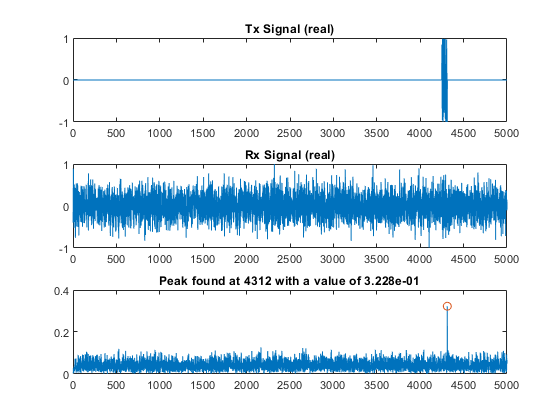

pulse_detector_reference;

## Simulate model and compare results to reference

if iscolumn(CorrFilter)
    CorrFilter = transpose(CorrFilter); % need row vector for filter block
end
SimTime = length(RxSignal) + WindowLen + 30;

% Simulate model
sim('pulse_detector_v2')


% Correlation filter output
FilterOutSL = squeeze(logsout.getElement('filter_out').Values.Data);
FilterValid = squeeze(logsout.getElement('filter_valid').Values.Data);
FilterOutSL = FilterOutSL(FilterValid);
compareData(real(FilterOut),real(FilterOutSL),{2 3 1},'ML vs SL correlator output (re)');


Maximum error for ML vs SL correlator output (re) out of 5000 values
 9.714451e-17 (absolute), 3.011348e-14 (percentage)


compareData(imag(FilterOut),imag(FilterOutSL),{2 3 2},'ML vs SL correlator output (im)');


Maximum error for ML vs SL correlator output (im) out of 5000 values
 1.526557e-16 (absolute), 1.328740e-13 (percentage)


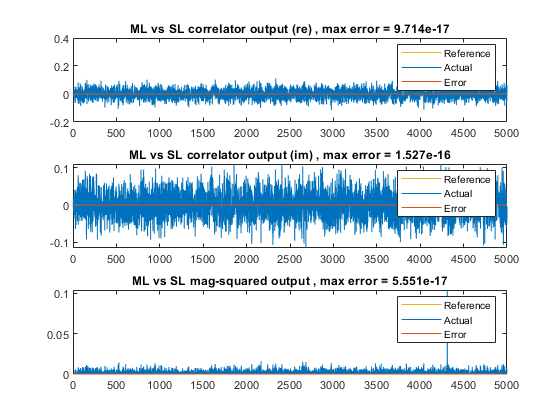


Maximum error for ML vs SL mag-squared output out of 5000 values
 5.551115e-17 (absolute), 5.327563e-14 (percentage)



% Magnitude squared output
MagSqSL = squeeze(logsout.getElement('mag_sq_out').Values.Data);
MagSqSL = MagSqSL(FilterValid);
compareData(MagSqOut,MagSqSL,{2 3 3},'ML vs SL mag-squared output');


% Peak value
MidSampleSL = squeeze(logsout.getElement('mid_sample').Values.Data);
Detected = squeeze(logsout.getElement('detected').Values.Data);
PeakSL = MidSampleSL(Detected>0);

fprintf('\nPeak location = %d, magnitude = %.3d using global max\n',location,peak);


Peak location = 4312, magnitude = 3.228e-01 using global max


fprintf('Peak location = %d, mag-squared = %.3d using local max\n',location_2,peak_2);

Peak location = 4312, mag-squared = 1.042e-01 using local max


fprintf('Peak mag-squared from Simulink = %.3d, error = %.3d\n',PeakSL,abs(peak_2-PeakSL));

Peak mag-squared from Simulink = 1.042e-01, error = 5.551e-17
